# SVM using various Kernels

## Data Preprocessing

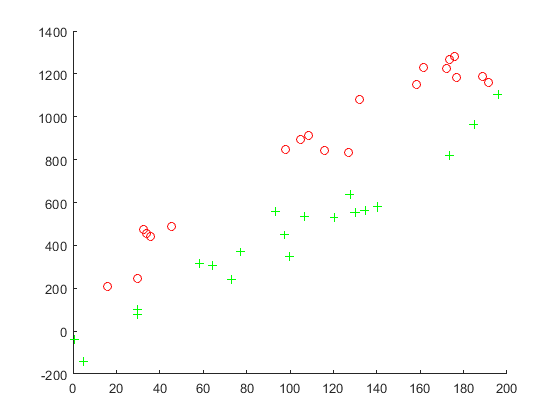

clear all;clc;
data=csvread('Classification.csv');

% Training & testing sets
[data_train,data_test] = holdout(data,80);
Xtrain = data_train(:,1:end-1); 
Ytrain = data_train(:,end);
Xtest = data_test(:,1:end-1);
Ytest = data_test(:,end);

% Scatter Plot of data
figure
hold on
X=[Xtrain;Xtest];Y=[Ytrain;Ytest];
scatter(X(Y==1,1),X(Y==1,2),'+g')
scatter(X(Y==-1,1),X(Y==-1,2),'or')
hold off

## Applying linear Kernel

linear_in=fitcsvm(Xtrain,Ytrain,'KernelFunction','linear');
linear_out=predict(linear_in,Xtest);
[~,acc_linear,fm_Linear]=confusionMatrix(Ytest,linear_out)

acc_linear = 1

fm_Linear = 1

## Decision Boundry in input space (Linear Kernel)

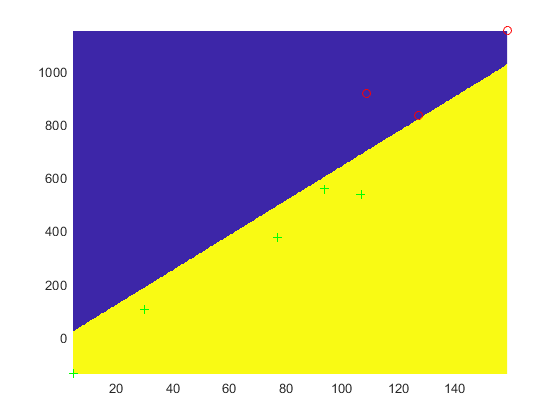

x1range=min(data(:,1)):0.5:max(data(:,1));
x2range=min(data(:,2)):0.5:max(data(:,2));

[x1 x2]=meshgrid(x1range,x2range);

X1n=reshape(x1,1,size(x1,2)*size(x1,1));
X2n=reshape(x2,1,size(x2,2)*size(x2,1));
Xn=[X1n' X2n'];

yn=predict(linear_in,Xn);
Yn=reshape(yn,size(x1));

figure
hold on
imagesc([min(Xtest(:,1)) max(Xtest(:,1))], [min(Xtest(:,2)) max(Xtest(:,2))], Yn);
scatter(Xtest(Ytest==1,1),Xtest(Ytest==1,2),'+g')
scatter(Xtest(Ytest==-1,1),Xtest(Ytest==-1,2),'or')
axis([min(Xtest(:,1)) max(Xtest(:,1)) min(Xtest(:,2)) max(Xtest(:,2))])
hold off

## Applying Polynomial Kernel (Poly2)

Mapping to higher Dimension

Xtr=[Xtrain(:,1).^2, Xtrain(:,2).^2, sqrt(2).*Xtrain(:,1).*Xtrain(:,2)]; 
Xte=[Xtest(:,1).^2, Xtest(:,2).^2, sqrt(2).*Xtest(:,1).*Xtest(:,2)];
fm_=[];

% for different values of 'C'
for c=[0.2,0.5,0.7] 
    
    % Applying Gradient Ascent
    alpha = grad_asc_poly(Xtr,Ytrain,c,2); 
    
    % Choosing data points for non-zero alphas
    alpha =alpha(alpha>0);Ys=Ytrain(alpha>0);Xs=Xtr(alpha>0,:);   
    
    % Calculating Weights & Bias
    W=sum(alpha.*Ys.*Xs); 
    bias=mean(Ys-(Xs*W'));
    
    % Predictions
    f=sign(Xte*W'+bias);
    [~,~,fm ] = confusionMatrix(Ytest,f);
    fm_=[fm_; c fm];   

end
% Optimal 'C' value
[max_fm, indx]=max(fm_(:,2));
c_opt=fm_(indx,1)

c_opt = 0.2000


% Support Vectors
alpha = grad_asc_poly(Xtr,Ytrain,c_opt,2);
alpha =alpha(alpha>0); Ys=Ytrain(alpha>0);
Xs=Xtr(alpha>0,:);

% Weights & Bias
W=sum(alpha.*Ys.*Xs)

W = 	1.0e+-8 *

    0.0050    0.1631    0.0359


bias=mean(Ys-(Xs*W'))

bias = -0.1212


% Predicted Values
f=sign(Xte*W'+bias);

% Confusion Matrix
    [~,accuracy,fmeasure ] = confusionMatrix(Ytest,f)

accuracy = 0.3750

fmeasure = NaN

## Plotting the Hyperplane in RKHS (Poly2)

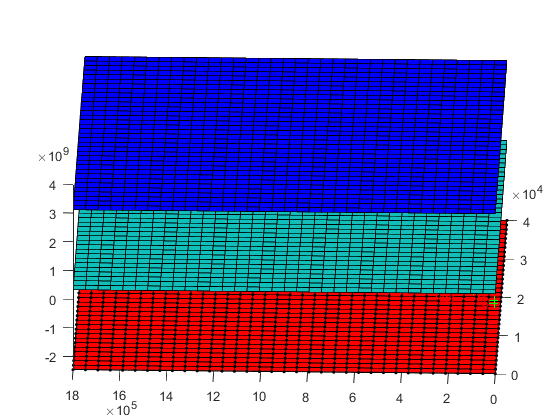

figure
hold on
scatter3(Xtr(Ytrain==1,1),Xtr(Ytrain==1,2),Xtr(Ytrain==1,3),'+g')
scatter3(Xtr(Ytrain==-1,1),Xtr(Ytrain==-1,2),Xtr(Ytrain==-1,3),'or')

syms x1 x2
fn=vpa((-bias-W(1)*x1-W(2)*x2)/W(3),4);
fsurf(fn);
fn1=vpa((-1-bias-W(1)*x1-W(2)*x2)/W(3),4);
fsurf(fn1,'.r');
fn2=vpa((1-bias-W(1)*x1-W(2)*x2)/W(3),4);
fsurf(fn2,'b');
view([-88.4 39.6])
hold off

## Decision Boundry in Input Space (Poly2)

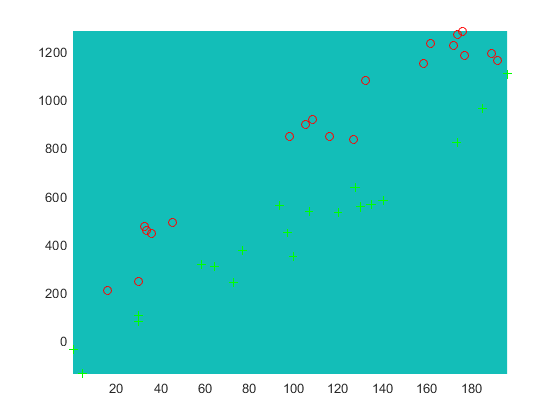

x1range=min(X(:,1)):1:max(X(:,1));
x2range=min(X(:,2)):1:max(X(:,2));
[x1 x2]=meshgrid(x1range,x2range);
x1p=reshape(x1,1,size(x1,2)*size(x1,1));
x2p=reshape(x2,1,size(x2,2)*size(x2,1));
Xp=[(x1p.^2)' ,(x2p.^2)', (x2p.*x1p)'];
ynp=sign(Xp*W'+bias);
Ynp=reshape(ynp,size(x1));

figure
hold on
imagesc([min(X(:,1)) max(X(:,1))], [min(X(:,2)) max(X(:,2))], Ynp);
scatter(X(Y==1,1),X(Y==1,2),'+g')
scatter(X(Y==-1,1),X(Y==-1,2),'or')
axis([min(X(:,1)) max(X(:,1)) min(X(:,2)) max(X(:,2))])
hold off

## Applying Gaussian Kernel (or RBF)

Xtest=data_test(:,1:end-1);Ytest=data_test(:,end);
Xtrain=data_train(:,1:end-1);Ytrain=data_train(:,end);

rbf_in=fitcsvm(Xtrain,Ytrain,'KernelFunction','rbf');
rbf_out=predict(rbf_in,Xtest);
[~,acc_RBF,fm_RBF]=confusionMatrix(Ytest,rbf_out)

acc_RBF = 0.3750

fm_RBF = NaN

## Decision Boundry in input space (RBF)

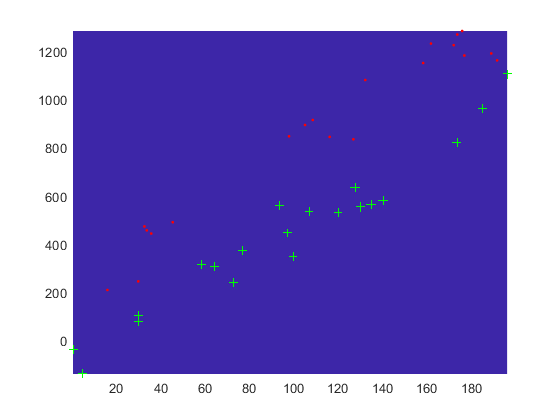

x1range=min(X(:,1)):0.5:max(X(:,1));
x2range=min(X(:,2)):0.5:max(X(:,2));
[x1 x2]=meshgrid(x1range,x2range);
X1n=reshape(x1,1,size(x1,2)*size(x1,1));
X2n=reshape(x2,1,size(x2,2)*size(x2,1));
Xn=[X1n' X2n'];

yn=predict(rbf_in,Xn);
Yn=reshape(yn,size(x1));

figure
hold on
imagesc([min(X(:,1)) max(X(:,1))], [min(X(:,2)) max(X(:,2))], Yn);
scatter(X(Y==1,1),X(Y==1,2),'+g')
scatter(X(Y==-1,1),X(Y==-1,2),'.r')
axis([min(X(:,1)) max(X(:,1)) min(X(:,2)) max(X(:,2))])
hold off